## **Proyecto 3 - Procesamiento de Señales**

**Juan Nicolás Quintero - Ana María Garzón - Juan Manuel Dávila**

El objetivo principal de este microproyecto 3 es diseñar y construir un algoritmo que utilice la FFT para enviar información de color en una foto a color; buscando pasar de una imagen a una señal para la cual se obtienen los coeficientes de Fourier y así seleccionar los coeficientes con base en un error. Estos coeficientes podrán luego ser enviados a través de un canal de comunicación. 

**Aplicación seleccionada: **Clasificación de naranjas

**Base de datos con las imagenes: **[https://github.com/anamarigarzon/Proyecto-Procesamiento-de-Senales/tree/main/imagenes](https://github.com/anamarigarzon/Proyecto-Procesamiento-de-Senales/tree/main/imagenes)

Para comenzar, usaremos una de las imagenes de la base de datos y la visualizaremos

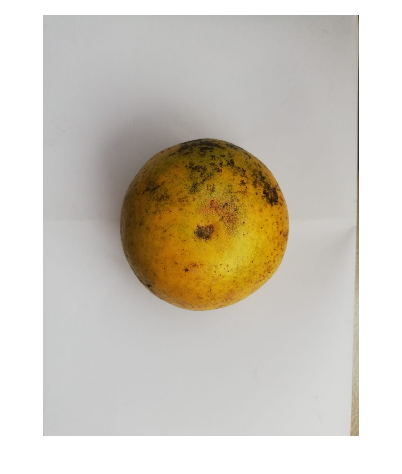

% lectura de imagen "amarillas\Natural\amarilla_luz_natural_no_flash_frente.jpeg"
% No olvidar editar ruta de imagen
% Ruta JM : "/Users/mac/Documents/Juan
% Manuel/UR/2022-2/Señales/git/Proyecto-Procesamiento-de-Senales/imagenes/imagenes/amarilla/Natural/amarilla_luz_natural_no_flash_abajo.jpeg")
I = imread("/Users/mac/Documents/Juan Manuel/UR/2022-2/Señales/git/Proyecto-Procesamiento-de-Senales/imagenes/amarilla/Natural/amarilla_luz_natural_no_flash_abajo.jpeg");
%I = imread("imagenes/amarilla/Natural/amarilla_luz_natural_no_flash_abajo.jpeg");
imshow(I) % visualización de la imagen

A continuación, distinguiremos la región de interés (naranja) del resto de la imagen

size(I);
e1 = [I(1,1,1) I(1,1,2) I(1,1,3)];
e2 = [I(1,size(I, 2),1) I(1,size(I, 2),2) I(1,size(I, 2),3)];
e3 = [I(size(I,1),1,1) I(size(I,1),1,2) I(size(I,1),1,3)];
e4 = [I(size(I,1),size(I,2),1) I(size(I,1),size(I,2),2) I(size(I,1),size(I,2),3)];

E = [e1;e2;e3;e4];
avg = mean(E,1) -50;

for i=1:1:size(I,1)
    for j=1:1:size(I,2)
        if I(i,j,1) > avg(1)
            if I(i,j,2) > avg(2)
                if I(i,j,3) > avg(3)
                    I(i,j,1) = 0;
                    I(i,j,2) = 0;
                    I(i,j,3) = 0;
                end
            end
        end
    end
end

imshow(I);

Ahora, visualizaremos la imagen con un mapa de calor por cada uno de los componentes RGB.

Comenzaremos con el rojo

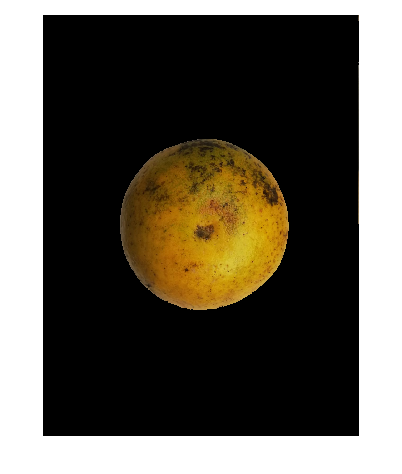

rojo = I(:,:,1);
mapajet = colormap(jet(256));

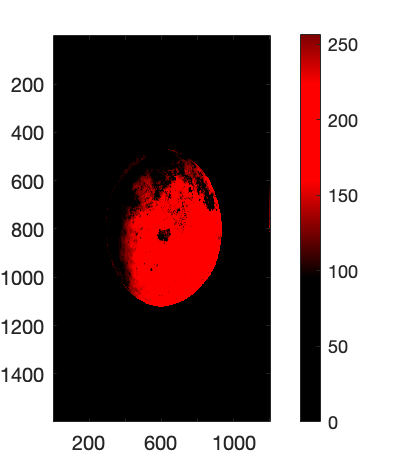

mapaRnuevo=[mapajet(:,1), zeros(256,1), zeros(256,1)];
image(rojo), colormap(mapaRnuevo), colorbar;

Ahora visualizaremos las componentes en verde

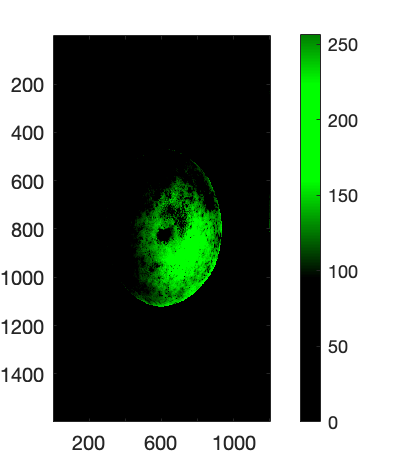

verde = I(:,:,2);
mapaVnuevo=[zeros(256,1), mapajet(:,1), zeros(256,1)];
image(verde), colormap(mapaVnuevo), colorbar;

Finalmente, los componentes en azul

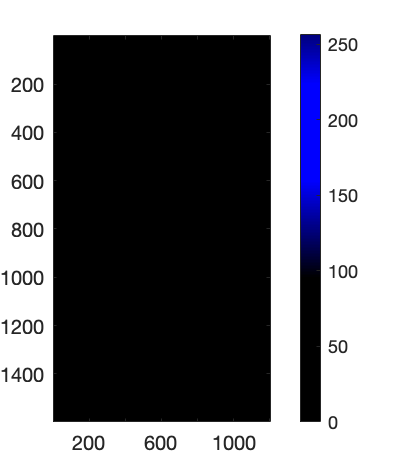

azul = I(:,:,3);
mapaAnuevo=[zeros(256,1), zeros(256,1),  mapajet(:,1)];
image(azul), colormap(mapaAnuevo), colorbar;

Para hacernos una idea de como está compuesta la imagen, podemos obtener la media de cada color, para la región de interés.

comp_rojo = [];
comp_verde = [];
comp_azul = [];

for i=1:1:size(I,1)
    for j=1:1:size(I,2)
        if I(i,j,1) > 0 && I(i,j,2) > 0 && I(i,j,3) > 0
                    comp_rojo = [comp_rojo, I(i,j,1)];
                    comp_verde = [comp_verde, I(i,j,2)];
                    comp_azul = [comp_azul, I(i,j,3)];
        end
    end
end

%media para la componente en rojo
media_rojo = mean(comp_rojo)

media_rojo = 149.5882

%media para la componente en verde
media_verde = mean(comp_verde)

media_verde = 106.6037

%media para la componente en azul
media_azul = mean(comp_azul)

media_azul = 18.5786

Lo que haremos ahora será crear un vector que tendrá primero las entradas de las componentes en rojo, luego las del verde y finalmente las del azul. Este vector será el que introduciremos en el algoritmo FFT.  La señal tendrá tres intervalos cada uno con los valores RGB extraídos de la región de interés y con 1024 muestras, para tener un vector final con 3092 muestras

[a,b] = size(comp_rojo);
tamano_intervalo = floor(b/1024);
comp_rojo_1024 = [];
comp_verde_1024 = [];
comp_azul_1024 = [];

for i=1:1:1024
    if tamano_intervalo * (i + 1) - 1 < b
        comp_rojo_1024 = [comp_rojo_1024, mean(comp_rojo(i*tamano_intervalo:i*tamano_intervalo+(tamano_intervalo-1)))];
        comp_verde_1024 = [comp_verde_1024, mean(comp_verde(i*tamano_intervalo:i*tamano_intervalo+(tamano_intervalo-1)))];
        comp_azul_1024 = [comp_azul_1024, mean(comp_azul(i*tamano_intervalo:i*tamano_intervalo+(tamano_intervalo-1)))];
    else
        comp_rojo_1024 = [comp_rojo_1024, mean(comp_rojo(i*tamano_intervalo:b))];
        comp_verde_1024 = [comp_verde_1024, mean(comp_verde(i*tamano_intervalo:b))];
        comp_azul_1024 = [comp_azul_1024, mean(comp_azul(i*tamano_intervalo:b))];
    end
end

vector_rgb = [comp_rojo_1024,comp_verde_1024,comp_azul_1024];
plot(vector_rgb)

Aplicaremos el algoritmo FFT al vector

% Aplicación del algorimo FFT
ftt=fft(vector_rgb);%transformada rápida de fourier

El número de componentes de frecuencia que se pueden obtener es:

A continuación construiremos el eje de la frecuencia para visualizar la FFT

% Creación del eje de frecuencia
w=1;%frecuencia fundamental
f=w/(2*pi);%frecuencia en Hz
fm=1000*f;%frecuencia de muestreo
t=0:1:3072;%eje de tiempo
ll=length(t);
factorr=ll/2;
delta=(fm/(2*factorr));%delta de frecuencias
freq_vector=[0:1:length(t)-2]*delta;%vector de frecuencias
fourier = abs(ftt)/factorr

fourier =   183.1065   65.4251   38.1430   19.3339   13.4009   11.0705    8.5126    6.8686    7.3659    3.5222    4.3795    5.9239    5.9430    3.3484    3.2873    2.8904    2.0121    3.0785    3.4704    1.9699    2.5649    2.3378    1.1575    2.2830    2.6014    1.3048    2.3136    2.9448    1.0174    1.4507    2.6038    1.0303    1.2703    2.1507    0.9903    1.2131    2.0743    0.8338    1.0531    2.0585    0.9446    0.9825    1.6736    0.8820    1.0682    1.4770    0.6821    0.9107    1.5075    0.8115


hold on

% Visualización de la FFT
%figure('color',[202 225 249]/255,'numbertitle','off');
%stem(freq_vector,fourier),grid
%xlabel('Frecuencia[Hz]','fontname','verdana','fontsize',8)
%ylabel('FFT Magnitud','fontname','verdana','fontsize',8)
%title('Gráfica de la Transformada de Fourier de x(t)')

El número de componentes de frecuencia (coeficientes) para que el error se encuentre entre 5% y el 10% es de

umbral = 0.005*fourier(1);
for i = 1:1:size(ftt, 2)
    ftt(i);
    if fourier(i) < umbral
        ftt(i) = ftt(i)*0;
    end
end
%stem(freq_vector,ftt),grid
ftt

ftt = 1.0e+05 *

   2.8134 + 0.0000i  -0.3192 - 0.9532i  -0.0586 - 0.5831i  -0.1034 + 0.2785i  -0.0057 - 0.2058i  -0.0110 - 0.1697i  -0.0231 + 0.1287i   0.0107 - 0.1050i  -0.0057 - 0.1130i   0.0003 + 0.0541i  -0.0132 - 0.0660i  -0.0288 - 0.0863i  -0.0022 + 0.0913i   0.0228 - 0.0461i   0.0091 - 0.0497i   0.0119 + 0.0428i   0.0052 - 0.0305i  -0.0045 - 0.0471i   0.0024 + 0.0533i   0.0071 - 0.0294i  -0.0015 - 0.0394i   0.0006 + 0.0359i  -0.0000 - 0.0178i  -0.0095 - 0.0338i   0.0028 + 0.0399i   0.0020 - 0.0199i  -0.0092 - 0.0343i  -0.0066 + 0.0448i   0.0074 - 0.0138i  -0.0068 - 0.0212i   0.0044 + 0.0398i   0.0101 - 0.0122i  -0.0072 - 0.0182i   0.0090 + 0.0318i   0.0060 - 0.0140i  -0.0048 - 0.0180i   0.0076 + 0.0309i   0.0000 + 0.0000i  -0.0035 - 0.0158i   0.0128 + 0.0289i   0.0047 - 0.0137i  -0.0027 - 0.0149i   0.0080 + 0.0245i   0.0000 + 0.0000i  -0.0019 - 0.0163i   0.0037 + 0.0224i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0063 + 0.0223i   0.0000 + 0.0000i


Reconstrucción con la IFFT de la señal con las componentes que cumplen con el error seleccionado.

% Recontrucción con IFFT

inv = ifft(ftt)

inv =    56.9664   69.5970   57.1872   63.8570   59.7402   57.1547   61.8281   52.6275   61.4771   51.5499   59.0862   52.7767   56.8460   54.2260   56.7019   54.9111   58.7896   55.6523   61.6902   57.9650   64.0646   62.3643   65.9719   67.7877   68.6085   72.6316   72.8475   76.2707   78.1389   79.4903   82.9180   83.4146   86.0964   88.0735   88.0843   92.1367   90.2531   94.1638   93.3361   94.1436   96.3966   93.7245   97.4992   94.7781   95.5505   97.5993   91.5626  100.4896   88.0522  101.2125


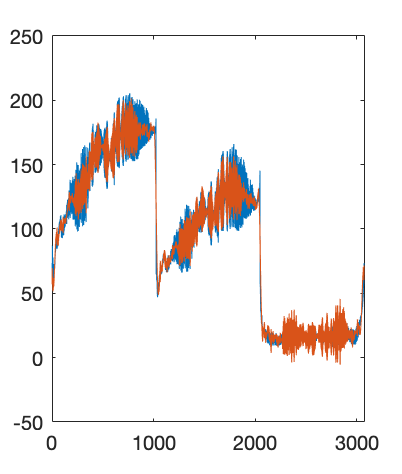

plot(inv)

Este procedimiento se lleva a cabo con cada una de las imagenes de la base de datos y se ha creado un archivo *.mat por cada señal. El nombre del archivo continene información sobre si la naranja es amarilla o verde, y las condiciones de iluminación de la imagen.

Finalmente, tomamos no de los conjuntos de coeficientes de señales de otro grupo y reconstruimos la señal.

% Cargar conjunto de señales de otro grupo
% Reconstrucción de la señal